Looking at whether the simulated lifetime is comparable to lifetime experimentally collected, when use the fitting parameters from this collected lifetime decay curve for the simulation.

The original purpose is to figure out why the simulated lifetime doesn't match the really lifetime of ACh sensor fluorescence used for get the fitting parameters.

SimulationName='simulation_test_lifetime_distribution_20220715';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

cd(savefolder)
mkdir(SimulationName)

filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/'

cd(filepath)

First I need a decay curve of PKA sensor.

'/Volumes/yaochen/Active/Pingchuan/2020FL/0922AKARFLEmx1Cre001/0922AKARFLEmx1Cre001FLIM016.mat' is used and loaded.

tau1 fixed at 2.14

tau2 fixed at 0.69

Do the fitting use the prf below.

prf and autofluorescence:

copyfile /Volumes/yaochen/Active/Pingchuan/prf/0903_prf_insight_pc.mat prf_PKA.mat
copyfile /Volumes/yaochen/Active/Pingchuan/simulation/AutoFluo0917.mat autofluorescence.mat

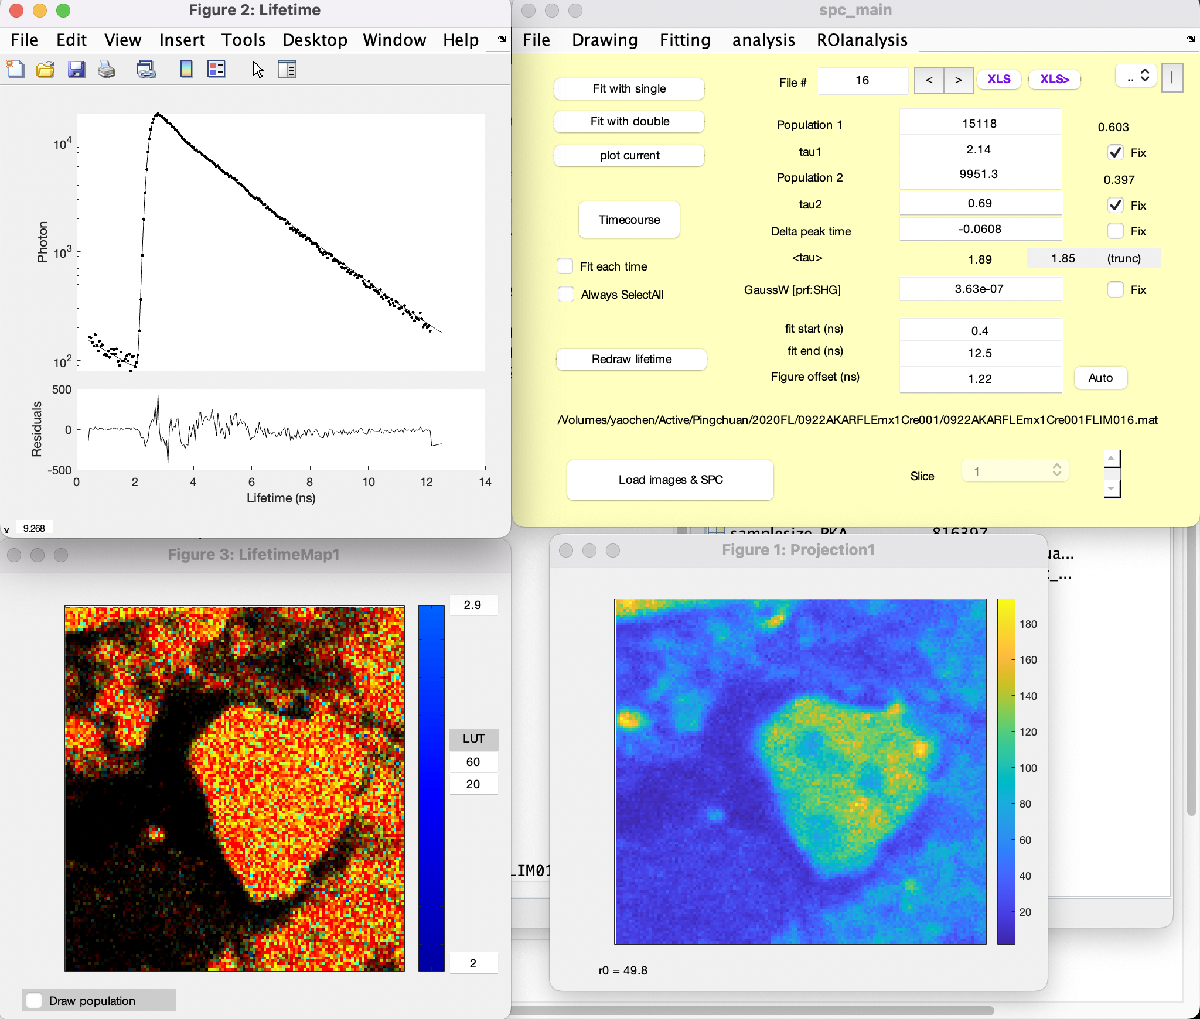

spc_openCurves('/Volumes/yaochen/Active/Pingchuan/2020FL/0922AKARFLEmx1Cre001/0922AKARFLEmx1Cre001FLIM016.mat',1)

Reading /Volumes/yaochen/Active/Pingchuan/2020FL/0922AKARFLEmx1Cre001/0922AKARFLEmx1Cre001FLIM016.mat


p1_PKA=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_PKA = 0.6046

p2_PKA=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_PKA = 0.3954

p1=0.6030; p2=0.3970

lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*spc.lifetimes{1};
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1})

empirical_lft_PKA = 4.3575

samplesize_PKA=round(sum(spc.lifetimes{1})*0.99)

samplesize_PKA = 808233

n_exp=spc.lifetimes{1};

% prf peak
load('prf_PKA.mat')
prf_peak_PKA=find(prf==max(prf))

prf_peak_PKA = 50

tau1_PKA=2.14

tau1_PKA = 2.1400

tau2_PKA=0.69

tau2_PKA = 0.6900

PKA_PopulationName='PKA_population_20220715'

PKA_PopulationName = 'PKA_population_20220715'

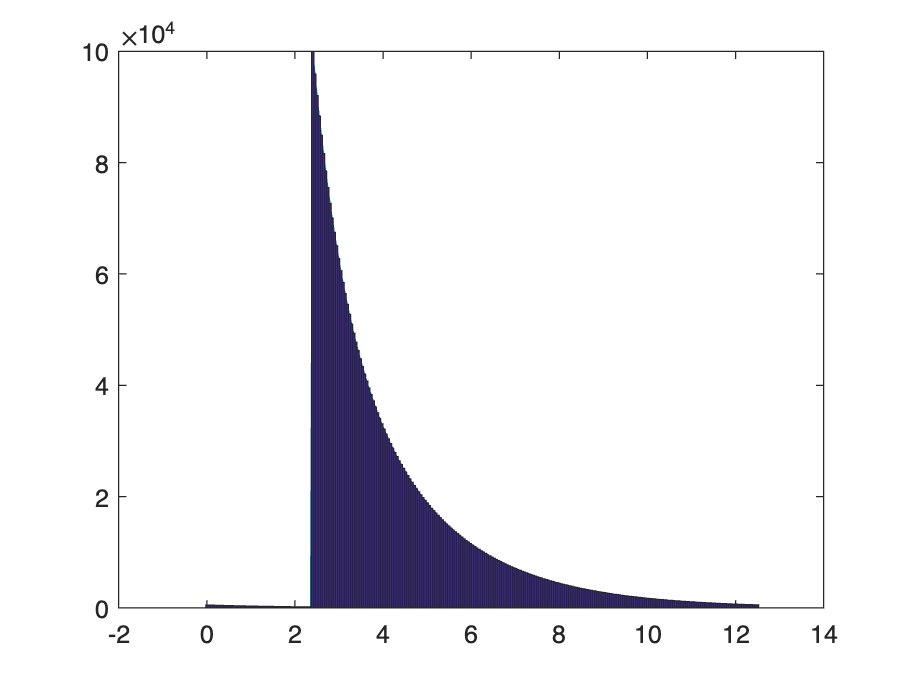

     3234073



GenPop256_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

save('PKA_simulation_parameters','tau1_PKA','tau2_PKA','p1_PKA','p2_PKA','samplesize_PKA','empirical_lft_PKA','n_exp')

cd(filepath)

mkdir([filepath,'/PKA/']);


AF=25487; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach(samplesize_PKA,0,AF,prf_peak_PKA,PKA_PopulationName, 'prf_PKA.mat', 'autofluorescence.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/PKA/',num2str(j)];
    save(samplename,'n','xout');
end

chan=1;
lft_steps=(1:1:256)*12.5/256;

    cd([filepath,'/PKA/']);
    delete FLIMSimulation_pm.mat

    matfiles = dir('*.mat');
    
    p=[];
    TauTrunc=[];
    chi2=[];
    avgTau=[];
    emp_lft=[];
    emp_lftTrunc=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*n;
        empirical_lft=sum(weight_n_lft)/sum(n)-(delta_peak_time-spc.fits{1}.beta5); % prf peak at 53. 53*12.5/256=2.5879
        
        p(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2(j)=spc.fits{chan}.redchisq; %chi2
        avgTau(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft(j)=empirical_lft; % empirical lft
        emp_lftTrunc(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction

fraction of photons from SHG: 0


    
    savename=[filepath,'simulation_result_PKA_20220715_2'];
    save(savename,'p','TauTrunc','chi2','avgTau','emp_lft','emp_lftTrunc');
    

% what if we remove the autofluorescence for fitting
chan=1;
lft_steps=(1:1:256)*12.5/256;
load('autofluorescence.mat')
autofluorescence=AutoFluo*AF;

    cd([filepath,'/PKA/']);
    
    matfiles = dir('*.mat');
    
    p_noauto=[];
    TauTrunc_noauto=[];
    chi2_noauto=[];
    avgTau_noauto=[];
    emp_lft_noauto=[];
    emp_lftTrunc_noauto=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n-autofluorescence;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*(n-autofluorescence);
        empirical_lft=sum(weight_n_lft)/sum(n-autofluorescence); % prf peak at 53. 53*12.5/256=2.5879
        
        p_noauto(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc_noauto(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2_noauto(j)=spc.fits{chan}.redchisq; %chi2
        avgTau_noauto(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft_noauto(j)=empirical_lft; % empirical lft
        emp_lftTrunc_noauto(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 4.5364e-13
fraction of photons from SHG: 4.5364e-13
fraction of photons from SHG: 4.5353e-13
fraction of photons from SHG: 4.5308e-13
fraction of photons from SHG: 4.5419e-13
fraction of photons from SHG: 4.5353e-13
fraction of photons from SHG: 4.5386e-13
fraction of photons from SHG: 4.5308e-13
fraction of photons from SHG: 4.5364e-13
fraction of photons from SHG: 4.533e-13
fraction of photons from SHG: 4.5297e-13
fraction of photons from SHG: 4.5297e-13
fraction of photons from SHG: 4.5342e-13
fraction of photons from SHG: 4.5264e-13
fraction of photons from SHG: 4.5264e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5297e-13
fraction of photons from SHG: 4.5286e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5353e-13
fraction of photons from SHG: 4.5264e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5275e-13
fraction of photons from SHG: 4.5275e-13
fraction of photo

fraction of photons from SHG: 4.5286e-13
fraction of photons from SHG: 4.5308e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5364e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5353e-13
fraction of photons from SHG: 4.5286e-13
fraction of photons from SHG: 4.533e-13
fraction of photons from SHG: 4.5353e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5319e-13
fraction of photons from SHG: 4.5275e-13
fraction of photons from SHG: 4.5342e-13
fraction of photons from SHG: 4.533e-13
fraction of photons from SHG: 4.5308e-13


    
    savename=[filepath,'simulation_result_PKA_noauto_20220715'];
    save(savename,'p_noauto','TauTrunc_noauto','chi2_noauto','avgTau_noauto','emp_lft_noauto','emp_lftTrunc_noauto');

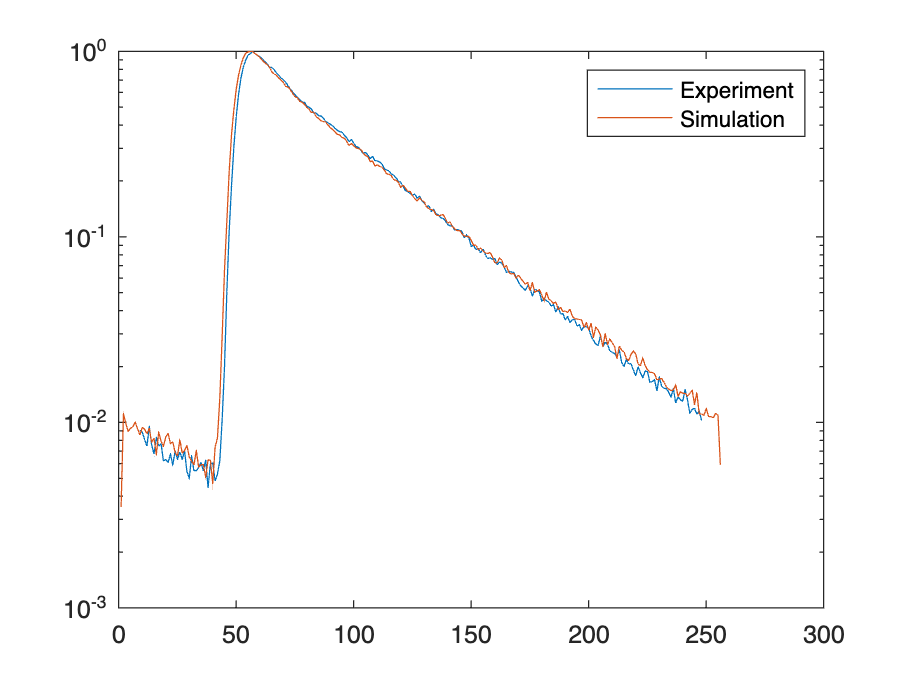

n_exp=n_exp/(max(n_exp));
load([filepath,'/PKA/1.mat'])
n_sim=n;
n_sim=n/max(n);

figure
semilogy(n_exp)
hold on
semilogy(n_sim)
legend('Experiment','Simulation')

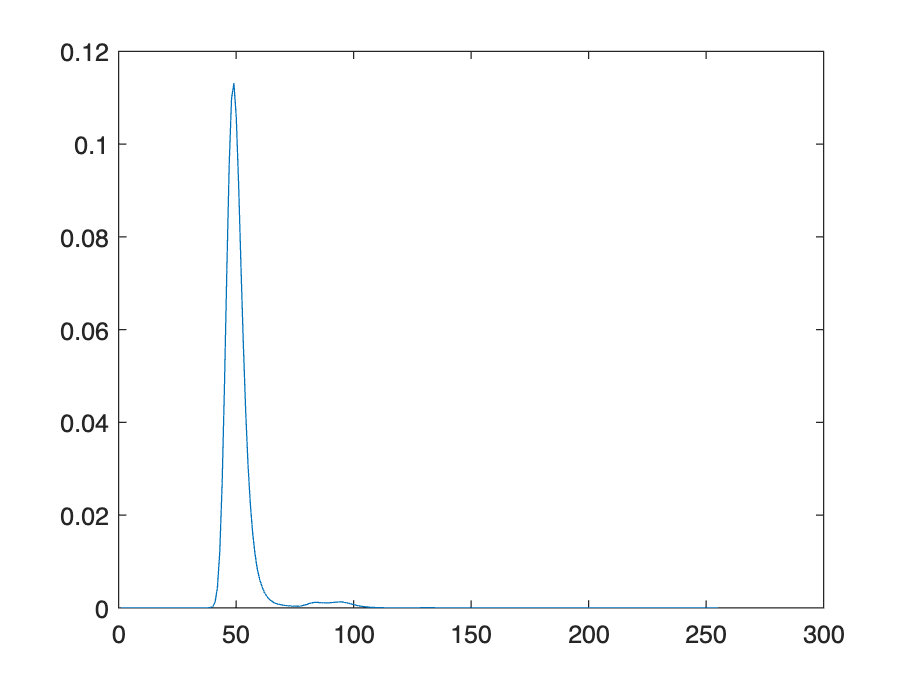

% what if remove the autofluorescence from the collected histogram first

% and then do the fitting. Use these fitting parameters to try the
% simulation



The simulated lifetime is always smaller than the real lifetime. Since afterpulse would increase the apparent lifetime, increasing the afterpulse could increase the lifetime. What 

Then simulate for ACh sensor.

load a ACh sensor decay curve.

'/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_ACh_FLIM_20220710/20220412_AchsensorHEK_003/20220412_AchsensorHEK_003FLIM131.mat'

SimulationName='simulation_test_lifetime_distribution_20220715';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/'

cd(filepath)

%prf
copyfile /Volumes/yaochen/Active/Pingchuan/prf/prf_InsightBottomGreen_20220628.mat prf_ACh.mat
copyfile /Users/pingchuanma/Desktop/ChenLab_Data/Simulation_ACh_FLIM_20220714/autofluorescence.mat autofluorescence_ACh.mat

load('prf_ACh.mat')
prf_peak_ACh=find(prf==max(prf))

prf_peak_ACh = 38

% load prf and do the fitting
p1_ACh=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_ACh = 0.8802

p2_ACh=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_ACh = 0.1198

tau1_ACh=spc.fits{1,1}.beta2

tau1_ACh = 3.0410

tau2_ACh=spc.fits{1,1}.beta4

tau2_ACh = 0.2826

lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*spc.lifetimes{1};
empirical_lft_ACh=sum(weight_n_lft)/sum(spc.lifetimes{1})

empirical_lft_ACh = 4.5775

samplesize_ACh=round(sum(spc.lifetimes{1})*0.99)

samplesize_ACh = 133550

ACh_PopulationName='ACh_population_20220715'

ACh_PopulationName = 'ACh_population_20220715'

n_exp_ACh=spc.lifetimes{1};

cd(filepath)

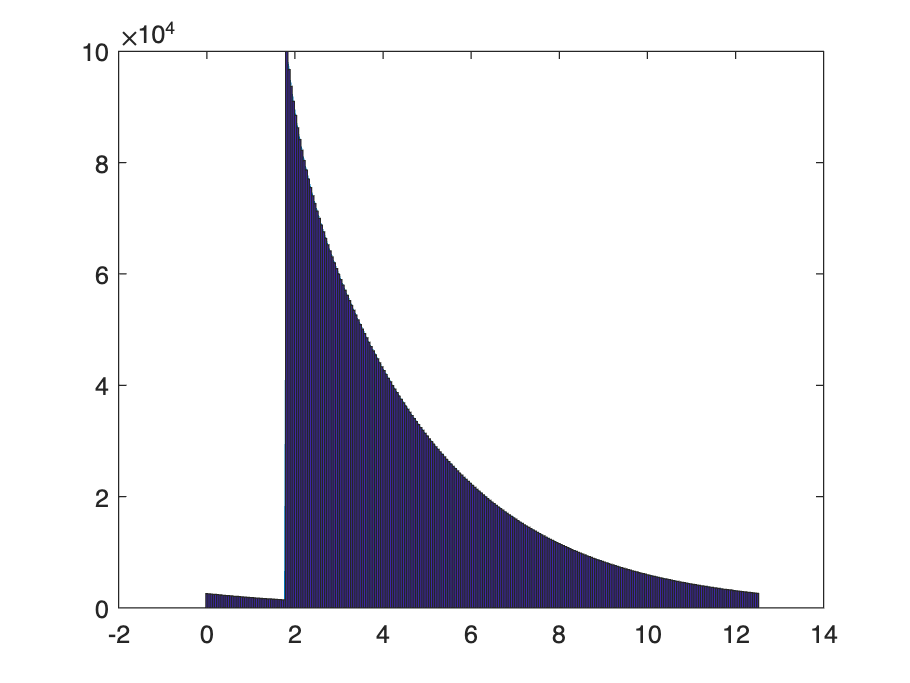

     5490648



GenPop256_Ach(100000,p1_ACh,p2_ACh,tau1_ACh,tau2_ACh,ACh_PopulationName,prf_peak_ACh)

save('ACh_simulation_parameters','tau1_ACh','tau2_ACh','p1_ACh','p2_ACh','samplesize_ACh','empirical_lft_ACh','n_exp_ACh')

mkdir([filepath,'/ACh/']);


AF=25487; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach(samplesize_ACh,0,AF,prf_peak_ACh,ACh_PopulationName, 'prf_ACh.mat', 'autofluorescence_ACh.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/ACh/',num2str(j)];
    save(samplename,'n','xout');
end

chan=1;
lft_steps=(1:1:256)*12.5/256;

    cd([filepath,'/ACh/']);
    
    matfiles = dir('*.mat');
    
    p=[];
    TauTrunc=[];
    chi2=[];
    avgTau=[];
    emp_lft=[];
    emp_lftTrunc=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*n;
        empirical_lft=sum(weight_n_lft)/sum(n); % prf peak at 53. 53*12.5/256=2.5879
        
        p(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2(j)=spc.fits{chan}.redchisq; %chi2
        avgTau(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft(j)=empirical_lft; % empirical lft
        emp_lftTrunc(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 2.241e-12
fraction of photons from SHG: 2.2513e-12
fraction of photons from SHG: 2.2423e-12
fraction of photons from SHG: 2.2371e-12
fraction of photons from SHG: 2.2465e-12
fraction of photons from SHG: 2.2461e-12
fraction of photons from SHG: 2.2434e-12
fraction of photons from SHG: 2.2449e-12
fraction of photons from SHG: 2.2442e-12
fraction of photons from SHG: 2.2495e-12
fraction of photons from SHG: 2.2465e-12
fraction of photons from SHG: 2.2503e-12
fraction of photons from SHG: 2.2462e-12
fraction of photons from SHG: 2.2494e-12
fraction of photons from SHG: 2.2391e-12
fraction of photons from SHG: 2.2463e-12
fraction of photons from SHG: 2.246e-12
fraction of photons from SHG: 2.246e-12
fraction of photons from SHG: 2.2395e-12
fraction of photons from SHG: 2.2464e-12
fraction of photons from SHG: 2.2526e-12
fraction of photons from SHG: 2.2479e-12
fraction of photons from SHG: 2.248e-12
fraction of photons from SHG: 2.246e-12
fraction of photons f

    
    savename=[filepath,'simulation_result_ACh_20220715'];
    save(savename,'p','TauTrunc','chi2','avgTau','emp_lft','emp_lftTrunc');

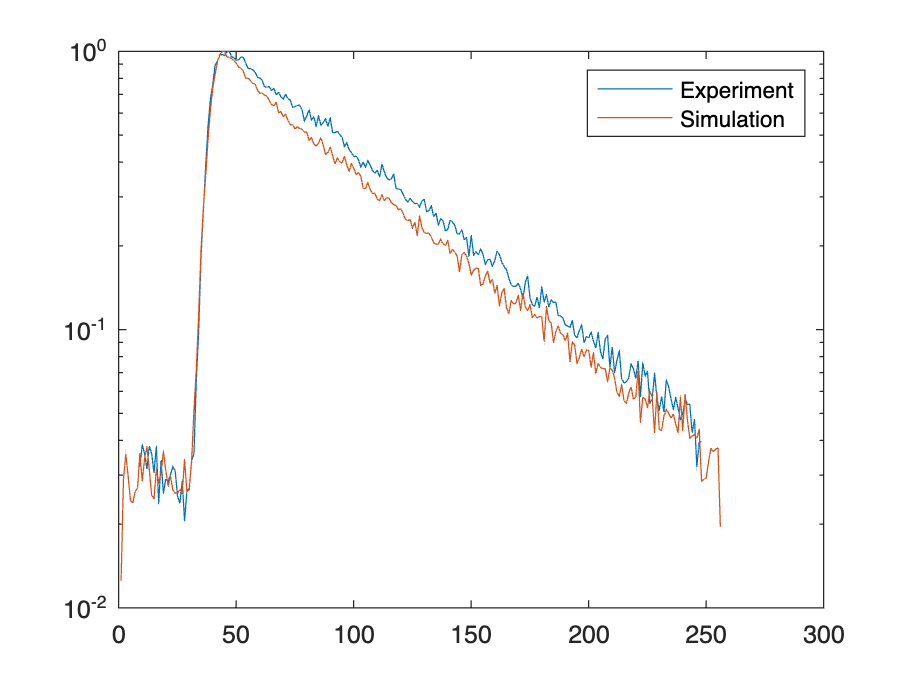

% load the experiment file first '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_ACh_FLIM_20220710/20220412_AchsensorHEK_003/20220412_AchsensorHEK_003FLIM131.mat'
n_exp_ACh=n_exp_ACh/(max(n_exp_ACh));
load([filepath,'/ACh/1.mat'])
n_sim_ACh=n/max(n);

figure
semilogy(n_exp_ACh)
hold on
semilogy(n_sim_ACh)
legend('Experiment','Simulation')

% what if we remove the autofluorescence for fitting
chan=1;
lft_steps=(1:1:256)*12.5/256;
load('autofluorescence_ACh.mat')
autofluorescence=AutoFluo0917*AF;

    cd([filepath,'/ACh/']);
    
    matfiles = dir('*.mat');
    
    p_noauto=[];
    TauTrunc_noauto=[];
    chi2_noauto=[];
    avgTau_noauto=[];
    emp_lft_noauto=[];
    emp_lftTrunc_noauto=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n-autofluorescence;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*(n-autofluorescence);
        empirical_lft=sum(weight_n_lft)/sum(n-autofluorescence); % prf peak at 53. 53*12.5/256=2.5879
        
        p_noauto(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc_noauto(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2_noauto(j)=spc.fits{chan}.redchisq; %chi2
        avgTau_noauto(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft_noauto(j)=empirical_lft; % empirical lft
        emp_lftTrunc_noauto(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 2.8891e-12
fraction of photons from SHG: 2.8997e-12
fraction of photons from SHG: 2.8904e-12
fraction of photons from SHG: 2.8839e-12
fraction of photons from SHG: 2.8786e-12
fraction of photons from SHG: 2.8875e-12
fraction of photons from SHG: 2.8841e-12
fraction of photons from SHG: 2.8899e-12
fraction of photons from SHG: 2.8945e-12
fraction of photons from SHG: 2.9036e-12
fraction of photons from SHG: 2.8904e-12
fraction of photons from SHG: 2.9012e-12
fraction of photons from SHG: 2.9037e-12
fraction of photons from SHG: 2.8926e-12
fraction of photons from SHG: 2.886e-12
fraction of photons from SHG: 2.8956e-12
fraction of photons from SHG: 2.8926e-12
fraction of photons from SHG: 2.8905e-12
fraction of photons from SHG: 2.886e-12
fraction of photons from SHG: 2.8921e-12
fraction of photons from SHG: 2.909e-12
fraction of photons from SHG: 2.8959e-12
fraction of photons from SHG: 2.893e-12
fraction of photons from SHG: 2.8912e-12
fraction of photons 

    
    savename=[filepath,'simulation_result_ACh_noauto_20220715'];
    save(savename,'p_noauto','TauTrunc_noauto','chi2_noauto','avgTau_noauto','emp_lft_noauto','emp_lftTrunc_noauto');

% what if we remove the afterpluse
cd(filepath)
afterpulse=zeros(1,256)+samplesize_ACh*0.01/256;

chan=1;
lft_steps=(1:1:256)*12.5/256;
load('autofluorescence_ACh.mat')
autofluorescence=AutoFluo*AF;

    cd([filepath,'/ACh/']);
    
    matfiles = dir('*.mat');
    
    p_noauto_noap=[];
    TauTrunc_noauto_noap=[];
    chi2_noauto_noap=[];
    avgTau_noauto_noap=[];
    emp_lft_noauto_noap=[];
    emp_lftTrunc_noauto_noap=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n-autofluorescence-afterpulse;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*(n-autofluorescence-afterpulse);
        empirical_lft=sum(weight_n_lft)/sum(n-autofluorescence-afterpulse); % prf peak at 53. 53*12.5/256=2.5879
        
        p_noauto_noap(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc_noauto_noap(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2_noauto_noap(j)=spc.fits{chan}.redchisq; %chi2
        avgTau_noauto_noap(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft_noauto_noap(j)=empirical_lft; % empirical lft
        emp_lftTrunc_noauto_noap(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 2.6835e-12
fraction of photons from SHG: 2.6764e-12
fraction of photons from SHG: 2.69e-12
fraction of photons from SHG: 2.673e-12
fraction of photons from SHG: 2.6771e-12
fraction of photons from SHG: 2.6849e-12
fraction of photons from SHG: 2.6962e-12
fraction of photons from SHG: 2.6916e-12
fraction of photons from SHG: 2.6736e-12
fraction of photons from SHG: 2.6983e-12
fraction of photons from SHG: 2.6908e-12
fraction of photons from SHG: 2.6734e-12
fraction of photons from SHG: 2.6857e-12
fraction of photons from SHG: 2.6817e-12
fraction of photons from SHG: 2.6851e-12
fraction of photons from SHG: 2.6796e-12
fraction of photons from SHG: 2.6908e-12
fraction of photons from SHG: 2.6792e-12
fraction of photons from SHG: 2.6669e-12
fraction of photons from SHG: 2.6802e-12
fraction of photons from SHG: 2.679e-12
fraction of photons from SHG: 2.6774e-12
fraction of photons from SHG: 2.692e-12
fraction of photons from SHG: 2.6821e-12
fraction of photons f

    
    savename=[filepath,'simulation_result_ACh_noauto_noap_20220715'];
    save(savename,'p_noauto_noap','TauTrunc_noauto_noap','chi2_noauto_noap','avgTau_noauto_noap','emp_lft_noauto_noap','emp_lftTrunc_noauto_noap');